On the HOME tab click on the Import Data button and select the required spreadsheet file.

# 4 | WORKING WITH SPREADSHEETS

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 10-Jun-2024 20:48:44

## Set up the Import Options and import the data

clear global
opts = spreadsheetImportOptions("NumVariables", 12);
% Specify sheet and range
opts.Sheet = "heart";
opts.DataRange = "A2:L919";
% Specify column names and types
opts.VariableNames = ["Age", "Sex", "ChestPainType", "RestingBP", "Cholesterol", "FastingBS", "RestingECG", "MaxHR", "ExerciseAngina", "Oldpeak", "ST_Slope", "HeartDisease"];
opts.VariableTypes = ["double", "categorical", "categorical", "double", "double", "double", "categorical", "double", "categorical", "double", "categorical", "categorical"];
% Specify file level properties
opts.ImportErrorRule = "error";
% Specify variable properties
opts = setvaropts(opts, ["Sex", "ChestPainType", "RestingECG", "ExerciseAngina", "ST_Slope"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, ["Age", "RestingBP", "Cholesterol", "FastingBS", "MaxHR", "Oldpeak", "HeartDisease"], "TreatAsMissing", '');
% Import the data
heart = readtable("/Users/juanheinklopper/Documents/MATLAB/MATLAB for Data Science/Data/heart.xlsx", opts, "UseExcel", false);
% Add appropriate units
heart.Properties.VariableUnits = {'Years' '' '' 'mm Hg' 'mg/dL' 'mg/dL' '' 'beats/min' '' '' '' ''}

heart = 918×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N               0        Up             0      
    49      F          NAP            160           180            0          Normal       156           N     

% Clear temporary variables
clear opts

## Introduction

We use Import Data functionality in MATLAB to import data in a spreadsheet. Once imported we can apply the concepts of exploratory data analysis (EDA) which we considered in the previous chapter.

## Summary statistics

We usually consider two types of summary statistics in EDA. That of a single variable and that of comparative summary statistics. In the former, we only consider a single variable as a whole. In the latter, we divided the data set by the unique elements of a categorical variable and summarize another variable by each of the groups formed by the classes of the categorical variable.

### Single variable summary statistics

The `summary` function summarizes each column in a `table` object (which contains the data in a spreadsheet which is in long-form tidy format).

% Summary statistics of all columns
summary(heart)

Variables:

    Age: 918×1 double

        Properties:
            Units:  Years
        Values:

            Min          28   
            Median       54   
            Max          77   

    Sex: 918×1 categorical

        Values:

            F      193   
            M      725   

    ChestPainType: 918×1 categorical

        Values:

            ASY      496   
            ATA      173   
            NAP      203   
            TA        46   

    RestingBP: 918×1 double

        Properties:
            Units:  mm Hg
        Values:

            Min           0   
            Median      130   
            Max         200   

    Cholesterol: 918×1 double

        Properties:
            Units:  mg/dL
        Values:

            Min           0   
            Median      223   
            Max         603   

    FastingBS: 918×1 double

        Properties:
            Units

Each individual column can be summarized by assigning the `summary` function to a variable. We use the variable name `s_stats` below.

% Create a variable of summary statistics
s_stats = summary(heart);

Now we can use dot notation to consider a specific column (variable). Note that this form of notation is why we do not allow illegal characters in the names of variables (column headers in the spreadsheet). If a name consists of more than one word, such as `Date of birth` it is best to use camelCase formatting, i.e. `dateOfBirth` (where the first letter is lowercase and each subsequent word starts with an uppercase letter and omitting all spaces). Another commonly used naming convention is snake_case, i.e. `Date_of_birth` (where space are replaced by underscores).

% Summary statistics of the Age column (variable)
s_stats.Age

ans = struct with fields:
           Size: [918 1]
           Type: 'double'
    Description: ''
          Units: 'Years'
     Continuity: []
            Min: 28
         Median: 54
            Max: 77
     NumMissing: 0


% Summary statistics of Sex
s_stats.Sex

ans = struct with fields:
           Size: [918 1]
           Type: 'categorical'
    Description: ''
          Units: ''
     Continuity: []
     Categories: {2×1 cell}
         Counts: [2×1 double]
     NumMissing: 0


It is sometimes useful to extract the values of a column as a vector and to assign it to a variable. Below, we use the `Age` column and assign it to the variable `age`. 

% Create a column vector of the Age variable
age = heart.Age;

The `mean` function can now be used to calculate the mean of the values in the vector.

% Mean of Age
mean(age)

ans = 53.5109

Below, we also calculate the sample variance, the sample standard deviation, minimum, maximum, range, median, first and third quartiles, and the interquartile range of the values in the `age` vector.

% Sample variance of Age (for a population variance use var(X,w=1))
var(age)

ans = 88.9743

% Sample standard deviation
std(age)

ans = 9.4326

% Minimum
min(age)

ans = 28

% Maximum
max(age)

ans = 77

% Range
max(age) - min(age)

ans = 49

% Median
median(age)

ans = 54

% First quartile
quantile(age,0.25)

ans = 47

% Third quartile
quantile(age,0.75)

ans = 60

% IQR
iqr(heart.Age)

ans = 13

% Frequency of classes in Sex variable
summary(heart.Sex)

     F      193 
     M      725 


### Summary statistics by classes of a categorical type variable

As mention, we can also calculate comparative summary statistics. We start by using a MATLAB app and summarize the `Age` column by the two unique classes in the `Sex` column. Be sure to name the analysis. Below, we use `age_by_sex`. 

Use the Task button on the LIVE EDITOR tab.

% Compute group summary
age_by_sex = groupsummary(heart,"Sex",["mean","median","mode","max","min", ...
    "range","std","var","nummissing"],"Age")

age_by_sex = 2×11 table
    Sex    GroupCount    mean_Age    median_Age    mode_Age    max_Age    min_Age    range_Age    std_Age    var_Age    nummissing_Age
    ___    __________    ________    __________    ________    _______    _______    _________    _______    _______    ______________

     F        193         52.492         53           54         76         30          46        9.5176     90.585           0       
     M        725         53.782         55           54         77         28          49        9.3979      88.32           0       


We also create a table of observed data or contingency table. This is done using a pivot table. We use the classes of the `Sex` column along the rows and the classes of the `ChestPainType` column along the columns. The resultant table shows the joint frequencies of each combination of the classes for the two categorical variables.

% Create pivoted table
sex_chestpaintype = pivot(heart, Rows="Sex", Columns="ChestPainType", ...
    IncludeTotals=true, RowLabelPlacement="rownames")

sex_chestpaintype = 3×5 table
                     ASY    ATA    NAP    TA    Overall_count
                     ___    ___    ___    __    _____________

    F                 70     60     53    10         193     
    M                426    113    150    36         725     
    Overall_count    496    173    203    46         918     


## Data visualization

The second important part of EDA is data visualization. We can also us a built-in app found in the Task button on the LIVE EDITOR tab to create plots.

### Single variable histogram

We start with histogram of the `Age` column.

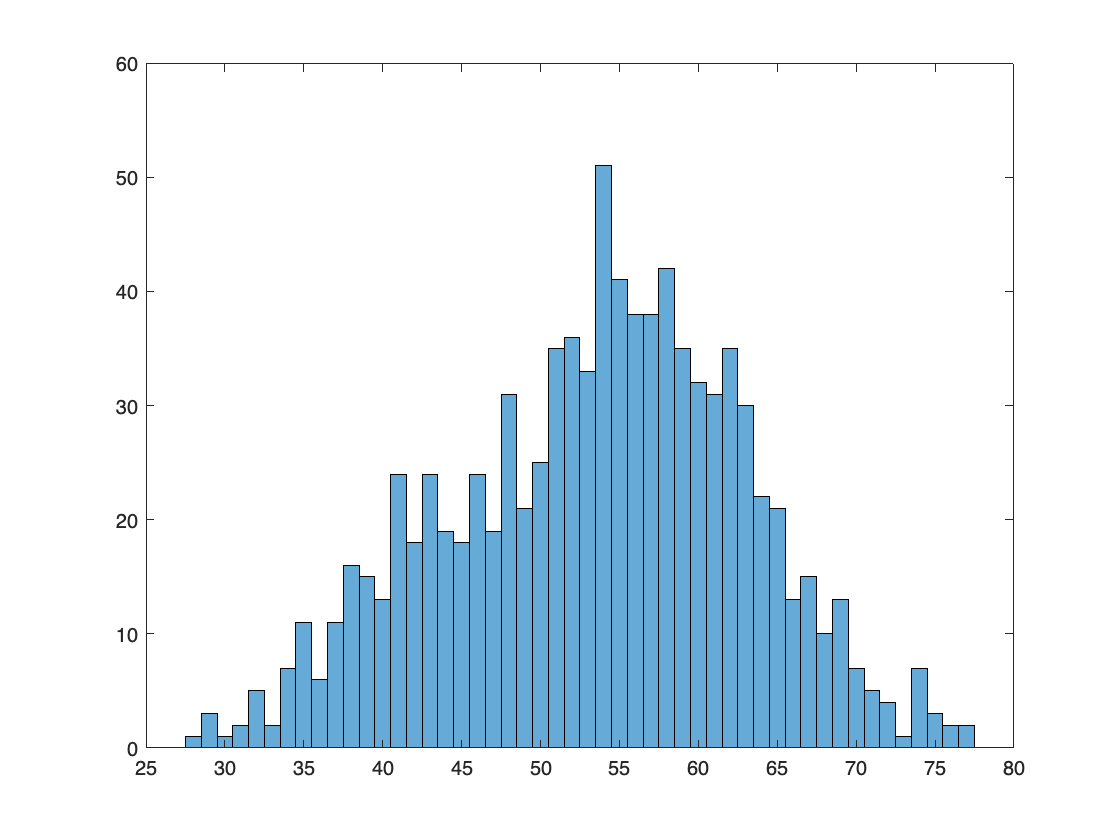

% Create histogram of heart.Age
hist_age = histogram(heart.Age,"DisplayName","Age");

### Single variable box-and-whisker plot

Next we create a box-and-whisker plot of the `RestingBP` column. This variable measures the resting blood pressure in mm of mercury. Instead of an app, we use code to create the plot.

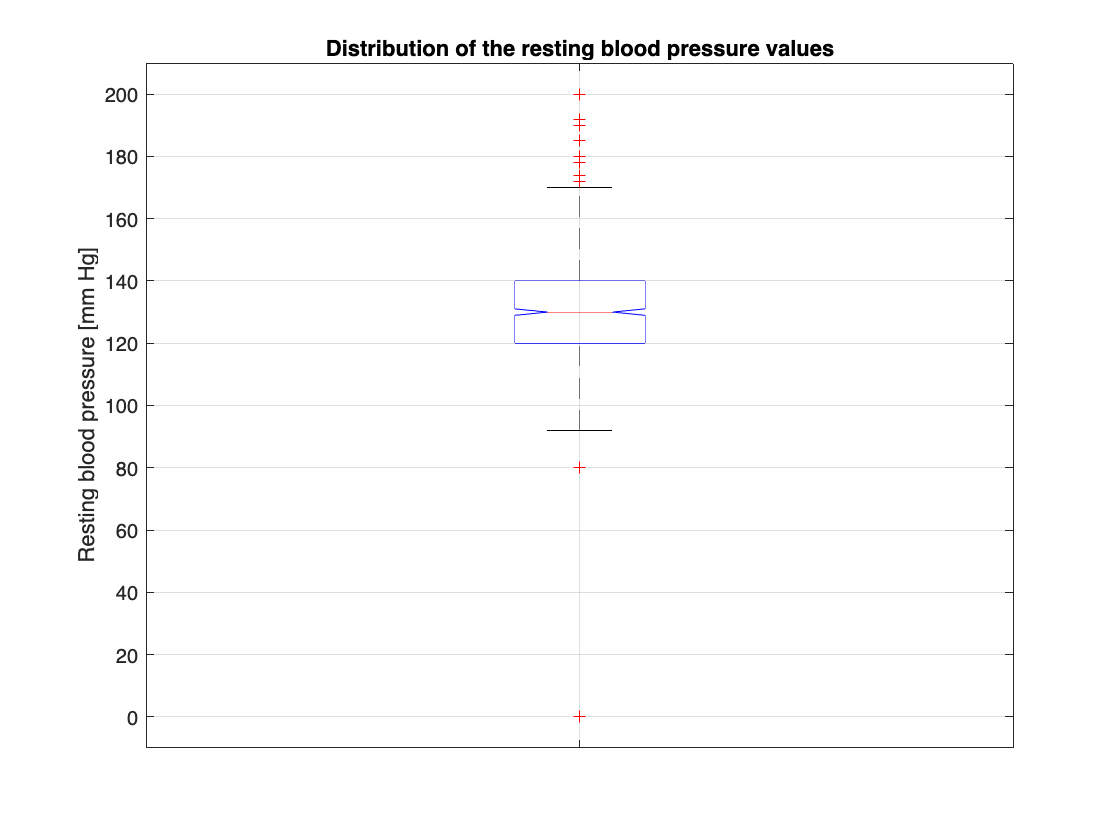

% Create a box plot of the RestingBP variable
boxplot(heart.RestingBP,'Notch','on')
grid on
title("Distribution of the resting blood pressure values")
ylabel("Resting blood pressure [mm Hg]")
xticklabels({""})
hold off

Note the suspected outliers beyond the lower and upper fences of the whiskers. The fences are at $1.5$ times the interquartile range below and above the first and third quartiles respectively.

### Single variable bar chart

We saw in the previous chapter that bar plots are good for displaying the frequencies or relative frequencies of the classes of a categorical variable. We use the `Sex` column below.

% Get frequencies of classes of Sex variable
summary(heart.Sex)

     F      193 
     M      725 


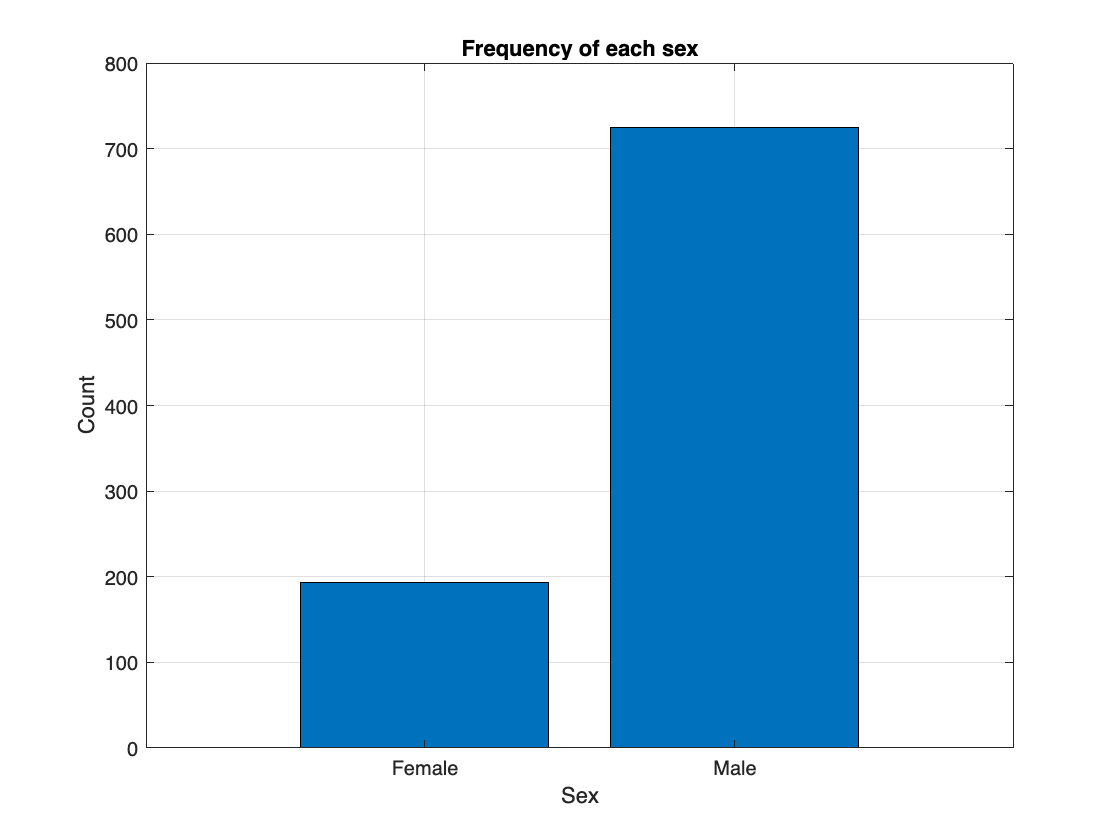

bar(["Female","Male"],[193,725])
grid on
title("Frequency of each sex")
xlabel("Sex")
ylabel("Count")
hold off

### Scatter plot for two-numerical variables

A scatter plot visualizes the relationship between two numerical variables. We start with the `Age` and `RestingBP` columns.

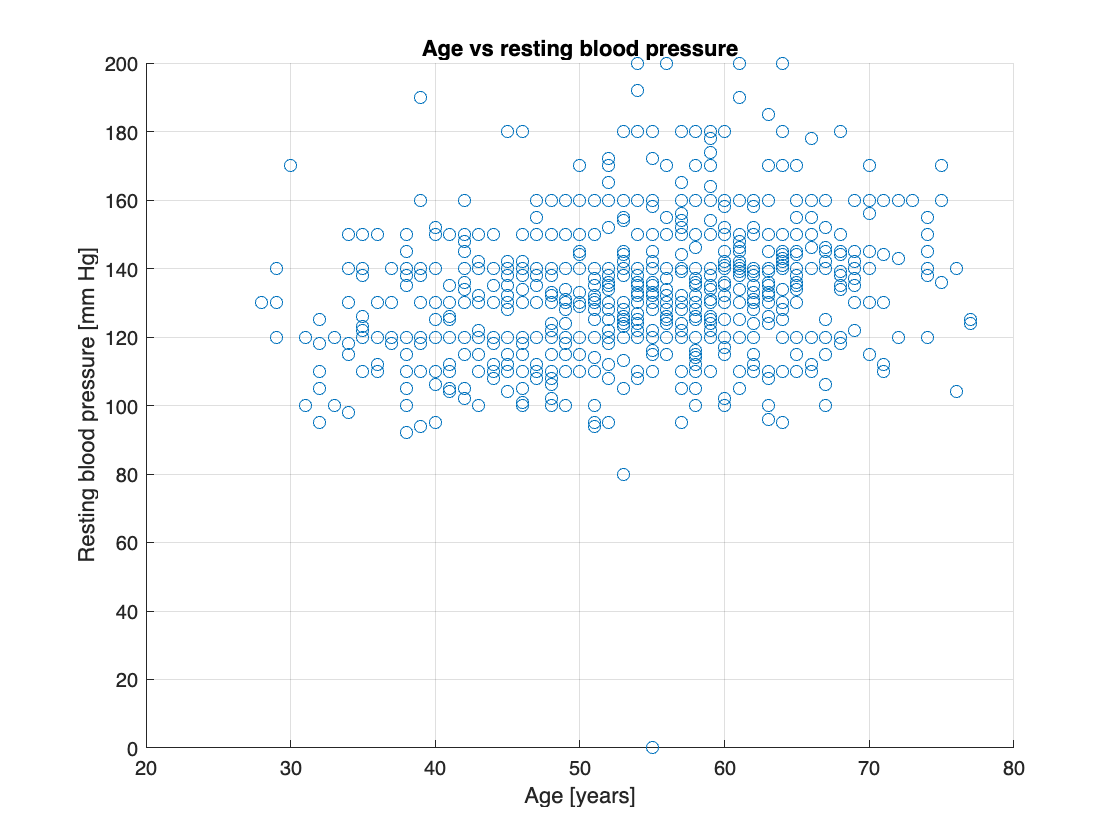

% Create a scatter plot of Age vs RestingBP
scatter(heart.Age,heart.RestingBP)
grid on
title("Age vs resting blood pressure")
xlabel("Age [years]")
ylabel("Resting blood pressure [mm Hg]")
hold off

### Scatter plot for two-numerical variables grouped by class

A scatter plot can also group the data by the unique elements of a categorical variable. Below we group the data by the two unique classes in the `Sex` column.

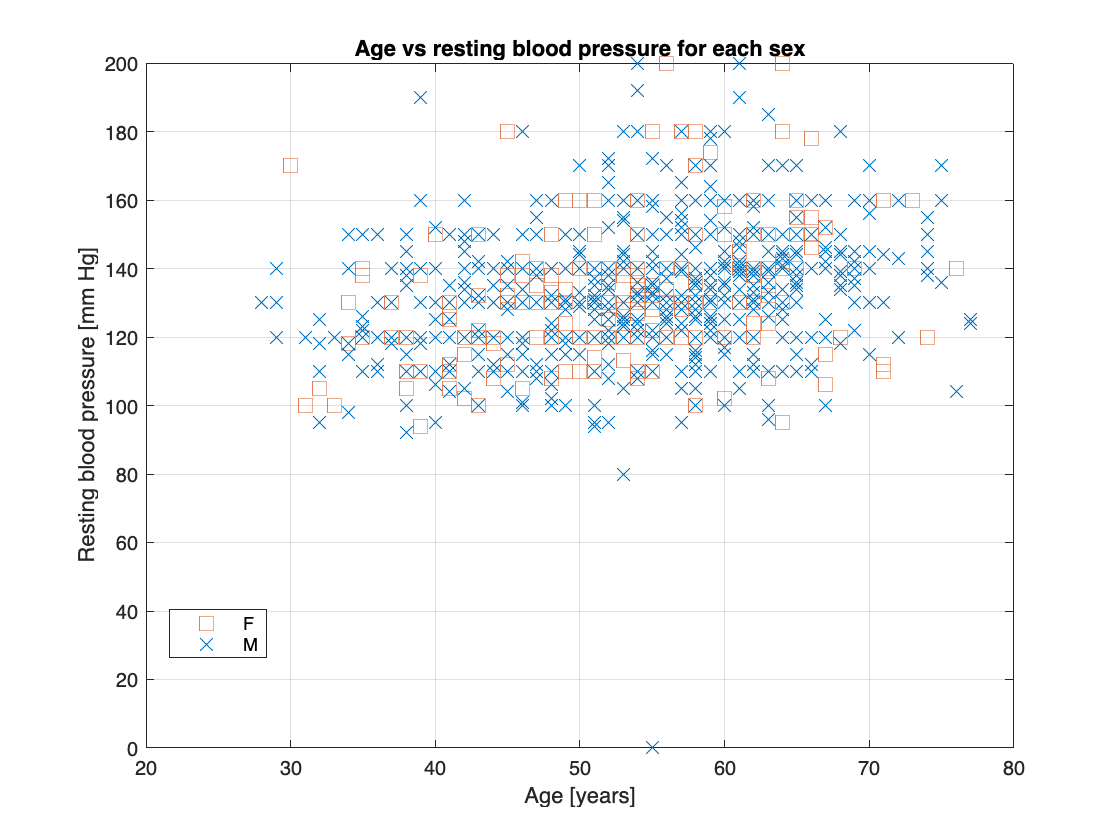

% Create a scatter plot of Age vs RestingBP for each class in Sex variable 
gscatter(heart.Age,heart.RestingBP,heart.Sex,[0.85 0.325 0.098; 0 0.447 0.741],'sx',[9 9])
grid on
title("Age vs resting blood pressure for each sex")
xlabel("Age [years]")
ylabel("Resting blood pressure [mm Hg]")
hold off

### Scatter plot of two-numerical variables including a third numerical variable

A scatter plot can also visualize a third numerical variable by considering color. Below we use the `Cholesterol` column.

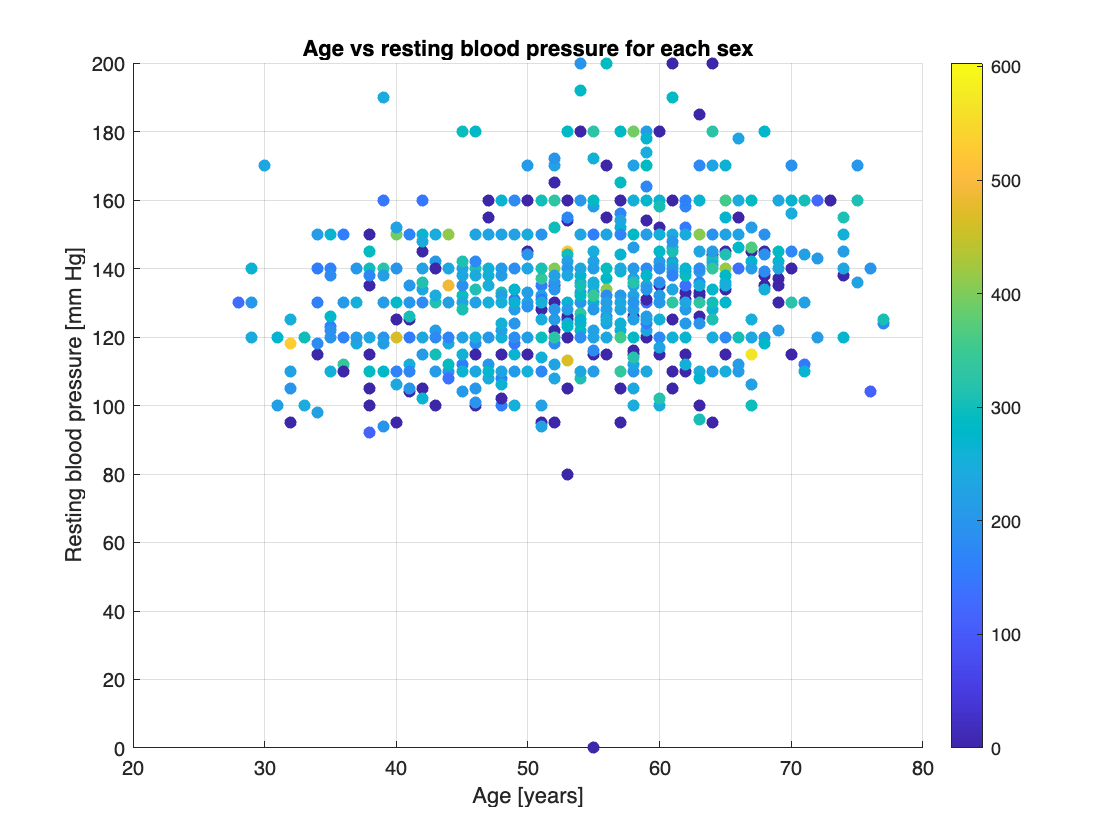

% Create a scatter plot of Age vs RestingBP and add the Cholesterol
% variable as numerical grouping column
scatter(heart,'Age','RestingBP','filled','ColorVariable','Cholesterol')
grid on
colorbar
title("Age vs resting blood pressure for each sex")
xlabel("Age [years]")
ylabel("Resting blood pressure [mm Hg]")
hold off

A bubble chart can also display a third numerical variable, but uses size as an indicator of the value of the third variable.

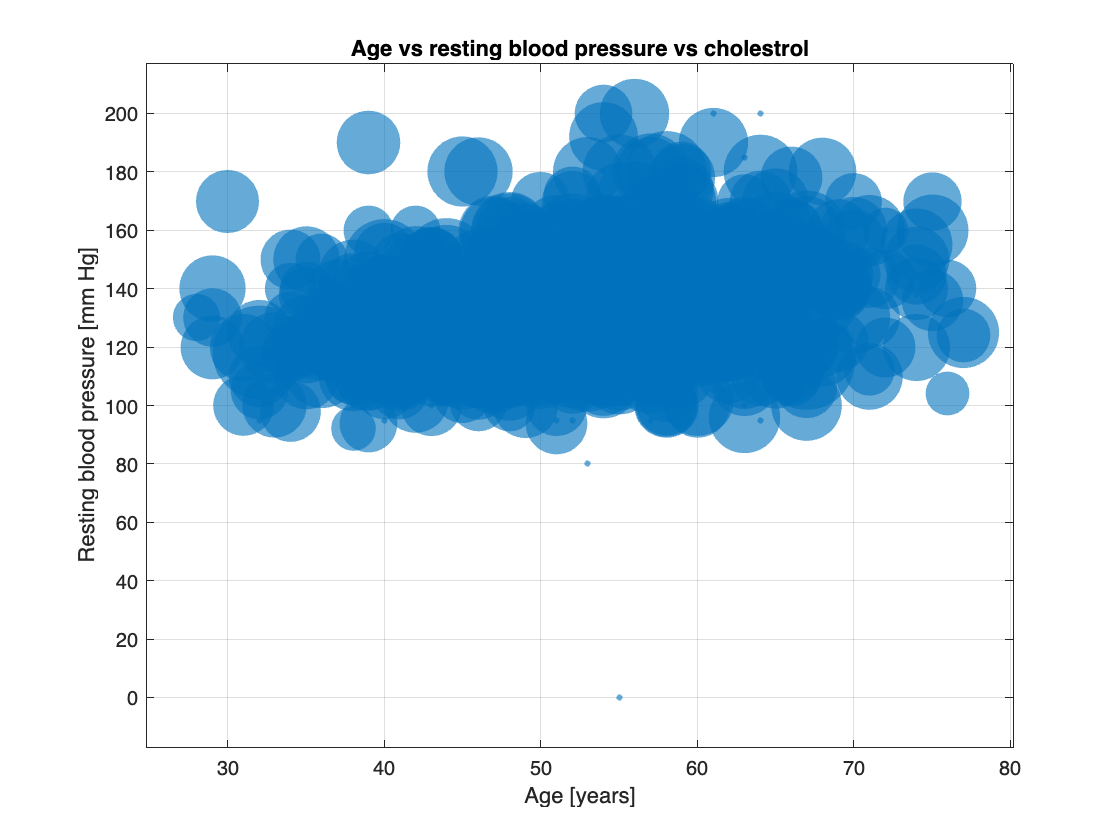

% Create a scatter plot of Age vs RestingBP and add the Cholesterol
% variable as numerical grouping column
bubblechart(heart,'Age','RestingBP','Cholesterol','MarkerEdgeColor','flat','MarkerEdgeAlpha',0.05)
grid on
title("Age vs resting blood pressure vs cholestrol")
xlabel("Age [years]")
ylabel("Resting blood pressure [mm Hg]")
hold off

### Box-and-whisker plot grouped by classes

As final example, we group the `Age` values by the two classes in the `Sex` column to create a box-and-whisker plot.

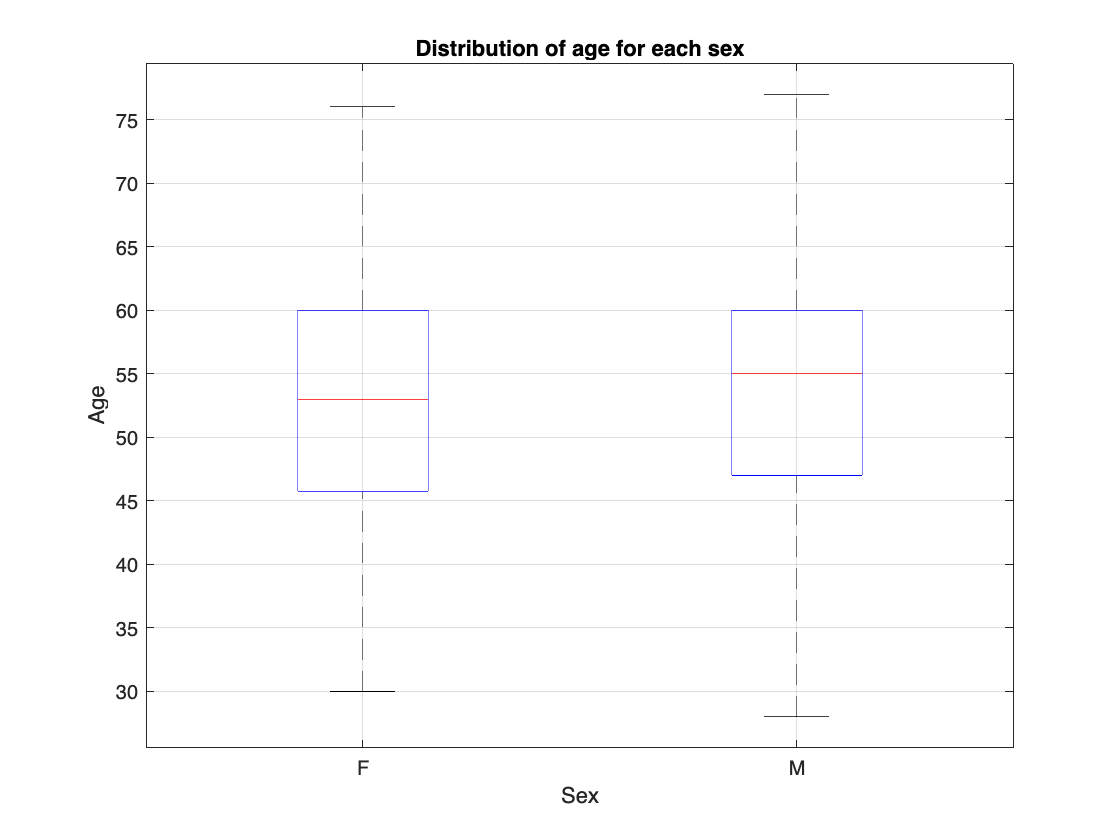

% Create a box plot of the Age variable for each of the classes in the Sex
% variable
boxplot(heart.Age,heart.Sex)
grid on
title("Distribution of age for each sex")
xlabel("Sex")
ylabel("Age")
hold off